## Zadanie 2) Optymalizacja regulatora PID

Na podstawie pomiarów odpowiedzi układu sterowania na skok jednostkowy wartości referencyjnej należy wykonać optymalizację nastaw regulatora wg krzywej narastania Gk(s) wartości wyjścia z obiektu sterowanego, wykorzystując optymalizację:

Warunek początkowy x0 = [0,0,0],  gdzie x0 = [Kp,Ki,Kd], estymowane Kp=x(1), Ki=x(2),  Kd=x(3)

Należy wykorzystać funkcję Matlaba C = pid(Kp,Ki,Kd) równanie reg w formie operatorowej

gdzie:

clear all
global G1
global t
G1=tf([0 1], [1 2 2.25 1.25]) % obiekt sterowania

G1 =
 
               1
  ---------------------------
  s^3 + 2 s^2 + 2.25 s + 1.25
 
Continuous-time transfer function.



Gk = tf([0 2], [1, 2, 2]) % model Gk

Gk =
 
        2
  -------------
  s^2 + 2 s + 2
 
Continuous-time transfer function.



t = 0:0.01:20;
%C = pid(x(1),x(2),x(3))         % optymalizowany kontroler

#### a)    Optymalizacja bez ograniczeń

Wykorzystując funkcje fminsearch, należy wykonać optymalizację nastaw regulatora PID tak, aby odpowiedź układu regulacji na zmianę wartości referencyjnej - skok jednostkowy była zbliżona do dynamiki modelu Gk(s) (dominująca stała czasowa τ≈1.25[s])

                       2

Gk(s) = -------------------

              s^2 + 2 s + 2

options = optimset();
x0 = [1, 1, 1];
figure;
[x,fval, exitflag] = fminsearch(@ident, x0, options)

x =     1.3117    1.3114    1.4697


fval = 0.4501

exitflag = 1

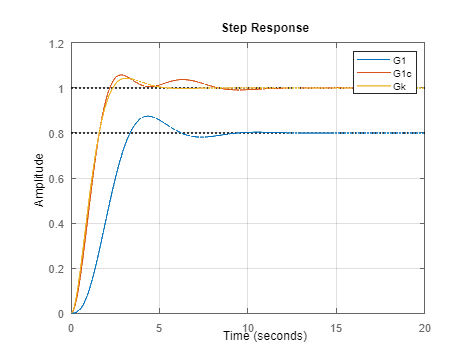


reg=pid(x(1), x(2), x(3));

G1c = feedback(reg*G1, 1);
Gk = tf([0 2], [1, 2, 2]);

figure;
step(G1 ,G1c, Gk, t);
legend(["G1", "G1c", "Gk"]);
grid on;

#### b)    Optymalizacja z ograniczeniami

Wykorzystując funkcje fmincon, należy wykonać optymalizację nastaw regulatora PID tak aby odpowiedz układu regulacji na zmianę wartości referencyjnej - skok jednostkowy była zbliżona do dynamiki modelu Gk(s) (dominująca stała czasowa τ≈1.25[s])

przy ograniczeniach na nastawy P,I,D, regulator rzeczywisty i P∈[0.2…5], I∈[0.2…10], D∈[0.2…10]

przy ograniczeniach równościowych i  nierównościowych spełniających kryterium Hurwitza dla transmitancji zastępczej układu regulator-obiekt.

Wskazówka:

Rozważyć rożne warunki początkowe np. x0 = [1,1,1],.

x0 = [1, 1, 1];
opts = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
figure;
x = fmincon(@ident ,x0, [], [], [], [], [], [], @ogr,opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    4.515151e+00     1.000e+00     1.000e+00     0.000e+00     1.337e+01  
    1          17    2.485853e+00     1.000e+00     4.035e-02     6.764e-01     1.059e+01  
    2          30    2.301667e+00     1.000e+00     4.035e-02     4.718e-01     7.059e+00  
    3          40    1.877046e+00     1.000e+00     1.176e-01     4.680e-01     3.393e+00  
    4          44    5.786556e-01     1.000e+00     1.000e+00     4.245e-01     1.267e+00  
    5          48    4.757695e-01     1.000e+00     1.000e+00     2.166e-01     7.760e-01  
    6          52    4.507668e-01     1.000e+00     1.000e+00     7.434e-02     2.284e-01  
    7          56    4.501868e-01     1.000e+00     1.000e+00     6.882e-03     5.467e-02  
    8          77    4.501868e-01     1.000e+00     5.585e-04     1.194e-06     5.

x =     1.3135    1.3115    1.4697


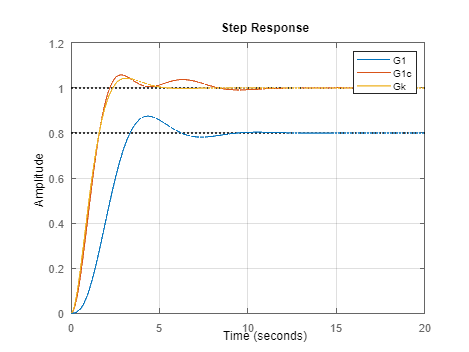


reg=pid(x(1), x(2), x(3));

G1c = feedback(reg*G1, 1);
Gk = tf([0 2], [1, 2, 2]);

figure;
step(G1, G1c, Gk, t);
legend(["G1", "G1c", "Gk"]);
grid on;

x0 = [3, 5, 3];
opts = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
figure;
x = fmincon(@ident, x0, [], [], [], [], [], [], @ogr, opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    6.968775e+01     1.000e+00     1.000e+00     0.000e+00     7.391e+01  
    1          15    5.264297e+01     1.000e+00     8.235e-02     7.157e+00     1.102e+01  
    2          21    5.106110e+01     1.000e+00     4.900e-01     3.239e+00     3.051e+00  
    3          25    5.017367e+01     1.000e+00     1.000e+00     1.643e+00     5.517e+00  
    4          29    4.570808e+01     1.000e+00     1.000e+00     1.475e+00     4.021e+00  
    5          34    4.084391e+01     1.000e+00     7.000e-01     2.976e+00     8.544e+00  
    6          38    3.221741e+01     1.000e+00     1.000e+00     1.327e+00     7.187e+00  
    7          47    1.169971e+01     1.000e+00     1.681e-01     3.554e+00     1.676e+01  
    8          62    1.158495e+01     1.000e+00     1.977e-02     1.017e+00     2.

x =     1.3111    1.3112    1.4694



reg=pid(x(1), x(2), x(3));

G1c = feedback(reg*G1, 1);
Gk = tf([0 2], [1, 2, 2]);

figure;
step(G1, G1c, Gk, t);
legend(["G1", "G1c", "Gk"]);
grid on;

x0 = [4, 9, 9];
opts = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
figure;
x = fmincon(@ident, x0, [], [], [], [], [], [], @ogr, opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    6.201345e+01     1.000e+00     1.000e+00     0.000e+00     4.451e+00  
    1           9    5.091414e+01     1.000e+00     7.000e-01     3.597e+00     5.993e+00  
    2          13    4.061620e+01     1.000e+00     1.000e+00     3.889e+00     4.486e+00  
    3          20    3.780569e+01     1.000e+00     3.430e-01     3.278e+00     1.772e+01  
    4          26    1.977548e+01     1.000e+00     4.900e-01     4.266e+00     2.291e+01  
    5          31    1.874636e+01     1.000e+00     7.000e-01     3.569e+00     5.801e+00  
    6          35    1.862771e+01     1.000e+00     1.000e+00     2.201e+00     4.492e+01  
    7          41    1.321379e+01     1.000e+00     4.900e-01     2.122e+00     4.879e+01  
    8          46    1.110959e+01     1.000e+00     7.000e-01     2.688e+00     8.

x =     1.3112    1.3127    1.4699



reg=pid(x(1), x(2), x(3));

G1c = feedback(reg*G1, 1);
Gk = tf([0 2], [1, 2, 2]);

figure;
step(G1 ,G1c, Gk, t);
legend(["G1", "G1c", "Gk"]);
grid on;

function blad = ident(x)
global G1 
global t

Gk = tf([0 2], [1, 2, 2]);

reg = pid(x(1), x(2), x(3));

G1c = feedback(reg*G1, 1);

[y1] = step(Gk, t); % wzor
[y2] = step(G1c, t); % dopasowanie

e = y1-y2;
blad = sum(e.^2);

end %ident

function [c, ceq] = Hurwitz(x)
global G1 
c = [0, 0];
ceq = [];

reg = pid(x(1), x(2), x(3));
G1c = feedback(reg*G1, 1);

a_vec = G1c.Denominator{1};

if all(a_vec > 0)
    %do nothing
elseif all(a_vec < 0)
    a_vec = -a_vec;
else
    %does not satisify 1st condition
    c = [abs(min(a_vec)), abs(min(a_vec))]; 
    return;
end %if

[H, delta] = hurwitz_matrix(a_vec);

if all(delta > 0)
    c = [-1, -1];
else
    c = [1, 1];
end %if

end %Hurwitz

function [c, ceq] = ogr(x)
    ceq = [];
    if 0.2<x(1) && x(1)<5 && 0.2<x(2) && x(2)<10 && 0.2<x(3) && x(3)<10
        [c, ceq] = Hurwitz(x);
    else
        c = [1, 1];
    end %if
end %ogr

function [H, delta] = hurwitz_matrix(p)

n = numel(p) - 1;
p1 = p(2:2:end);
p2 = p(1:2:end);

if isnumeric(p)
    H = zeros(n, n);
    delta = zeros(n, 1);
else
    H = zeros(n, n);
    delta = sym(zeros(n, 1));
end

i = 0;
for k = 1:n
    if mod(k, 2)
        H(k, i+[1:numel(p1)]) = p1;
    else
        H(k, i+[1:numel(p2)]) = p2;
    end
end

for k = 1:n
    delta(k) = det(H(1:k, 1:k));
end

end